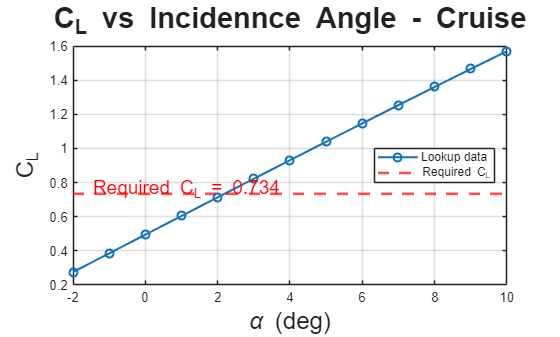

baseDir = fileparts(matlab.desktop.editor.getActiveFilename);
filePath = fullfile(baseDir, '../+lookup/+aerodynamics/cruise_lookup_table.mat');
S = load(filePath);
R = S.Results;

span = 73.5;
mach = 0.7;
rootChord = 15.2;
altitude = 9500;

span = S.spanVec(nearestIndex(S.spanVec,span));
mach = S.machVec(nearestIndex(S.machVec,mach));
rootChord = S.rootChordVec(nearestIndex(S.rootChordVec,rootChord));
altitude = S.altVec(nearestIndex(S.altVec,altitude));

i = [R.WingSpan] == span & [R.Mach] == mach & [R.RootChord] == rootChord & [R.Altitude] == altitude;

A = [R(i).Alpha];
CL = [R(i).CL]+0.1;
CD = [R(i).CD]+0.018;

[A,ord] = sort(A);
CL = CL(ord);
CD = CD(ord);

LD = CL ./ CD;

alpha = 2.2;
CLq = interp1(A,CL,alpha,'linear','extrap');
CDq = interp1(A,CD,alpha,'linear','extrap');
LDq = CLq / CDq;

CL_required = 0.734;

figure
plot(A,CL,'-o','LineWidth',1.5)
hold on

% Horizontal line at required CL
yline(CL_required,'r--','LineWidth',2)

% Label it
text(min(A)+0.5, CL_required+0.02, 'Required C_L = 0.734', ...
    'Color','r','FontSize',14)

title('C_L vs Incidennce Angle - Cruise','FontSize',22)
xlabel('\alpha (deg)','FontSize',18)
ylabel('C_L','FontSize',18)
grid on
legend('Lookup data','Required C_L','Location','best')

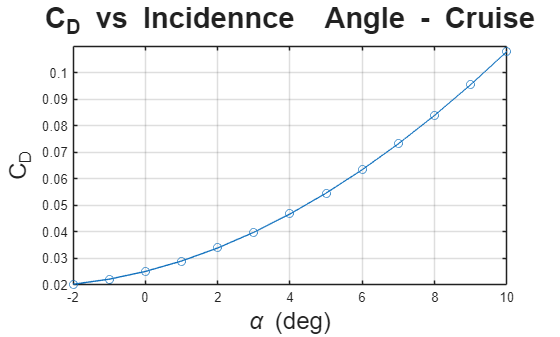

figure
plot(A,CD,'-o')
title('C_D vs Incidennce  Angle - Cruise','FontSize',22)
xlabel('\alpha (deg)','FontSize',18)
ylabel('C_D','FontSize',18)
grid on

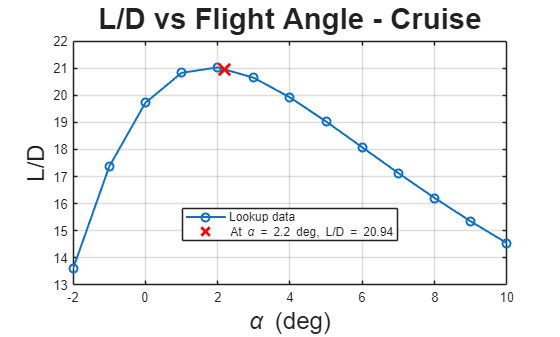


figure
plot(A,LD,'-o','LineWidth',1.5)
hold on
plot(alpha,LDq,'rx','MarkerSize',12,'LineWidth',2)
title('L/D vs Flight Angle - Cruise','FontSize',22)
xlabel('\alpha (deg)','FontSize',18)
ylabel('L/D','FontSize',18)
grid on
legend('Lookup data', sprintf('At \\alpha = %.1f deg, L/D = %.2f',alpha,LDq), 'Location','best')


fprintf('At alpha = %.2f deg:\n', alpha);

At alpha = 2.20 deg:


fprintf('CL   = %.4f\n', CLq);

CL   = 0.7354


fprintf('CD   = %.4f\n', CDq);

CD   = 0.0351


fprintf('L/D  = %.4f\n', LDq);

L/D  = 20.9394


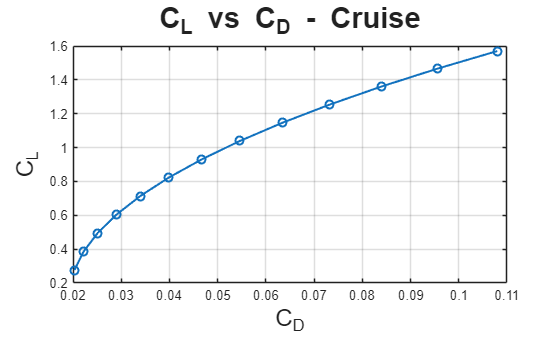


figure
plot(CD, CL, '-o', 'LineWidth', 1.5)
grid on
xlabel('C_D', 'FontSize', 18)
ylabel('C_L', 'FontSize', 18)
title('C_L vs C_D - Cruise', 'FontSize', 22)


function k = nearestIndex(vec,x)
    [~,k] = min(abs(vec-x));
end